# Binary Phase Shift Keying

## Generate Data for Transmission

% Seed the random number generator
rng(1)
N=1000; % Length of the data
dat=sign(randn(N,1))+1i*0; % Generate random data
txname='tx_bpsk_1.dat'; % name of tx data file

% Uncomment the following to pad the beginning and end of the TX data with
% -1s and 1s
%
% N = 1000 - 100*2;
% dat=sign(randn(N,1))+1i*0; % Generate random data
% negative = -1*ones(100,1)+j*zeros(100,1);
% positive = 1*ones(100,1)+j*zeros(100,1);
% dat= [negative.' dat.' positive.'].'

% Upsample the data
pulse_width = 100;
x_us=upsample(dat,pulse_width);

% Convolve the signal with a pulse
pulse=ones(pulse_width,1);
x=conv(x_us,pulse);

% Write TX data to a file
write_usrp_data_file(x,txname)

## Read in Transmitted Data

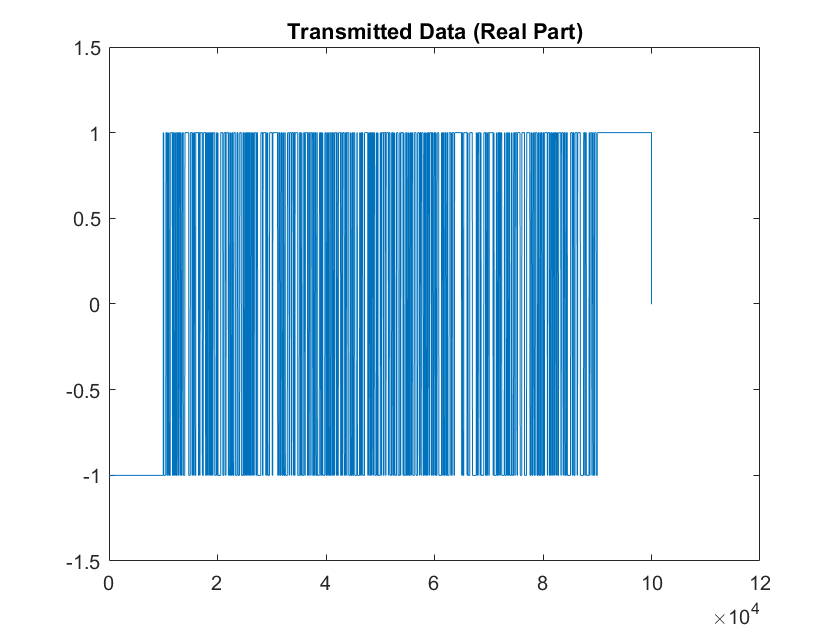

% Read in the Transmitted Data
txname='tx_x7.dat';
dat=read_usrp_data_file(txname);

% Plot the real portion of the data (we sent a purely real signal)
figure
plot(real(dat))
title('Transmitted Data (Real Part)')
ylim([-1.5,1.5]);

## Read in Received Data

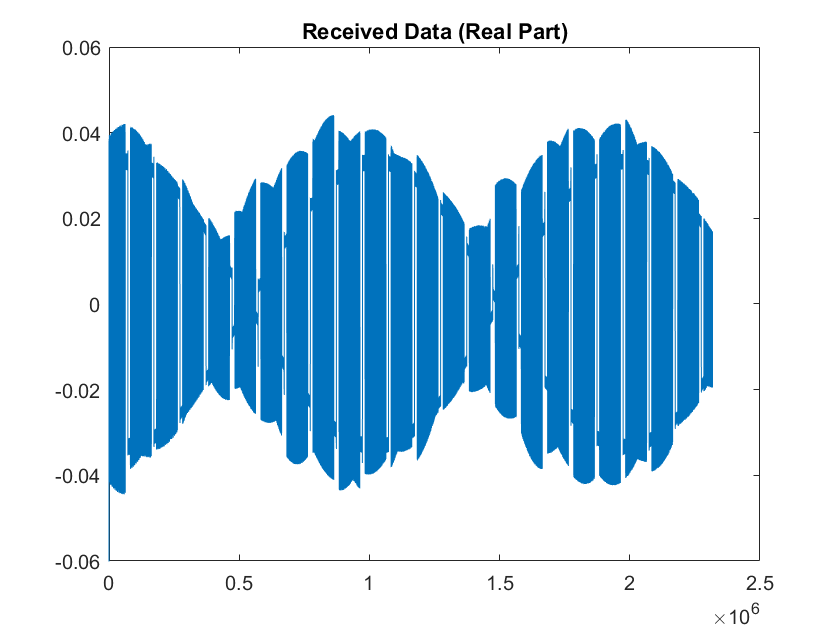

% Read in the Received Data
rxname='rx_x7_repeat.dat';
read=read_usrp_data_file(rxname);

% Plot the real and imaginary part of received signal
% Note that the signal was sent repeatedly
figure
plot(real(read))
ylim([-0.06,0.06]);
title('Received Data (Real Part)')

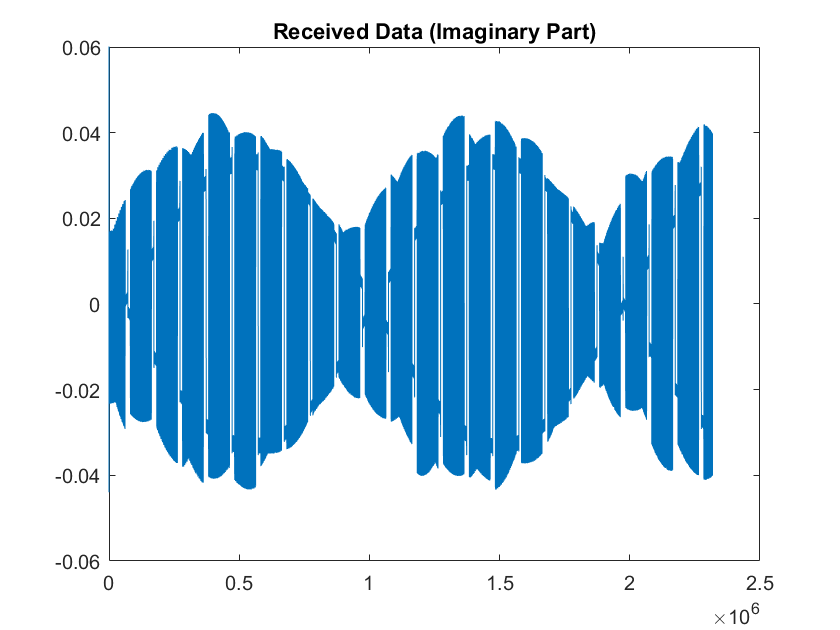

figure
plot(imag(read))
ylim([-0.06,0.06]);
title('Received Data (Imaginary Part)')

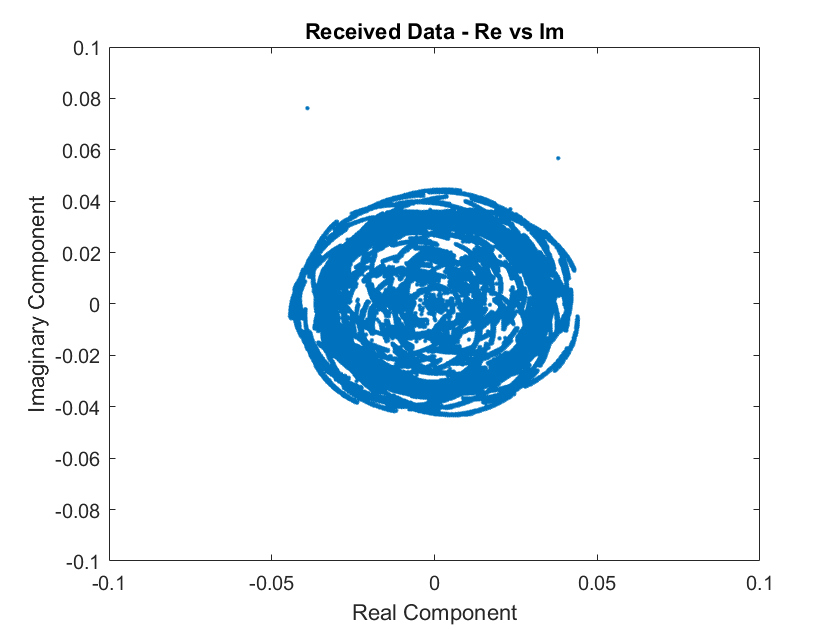


% Plot the real part vs the imaginary part
figure
plot(real(read),imag(read),'.')
xlim([-0.1,0.1]);
ylim([-0.1,0.1]);
title('Received Data - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Autocorrelate received signal

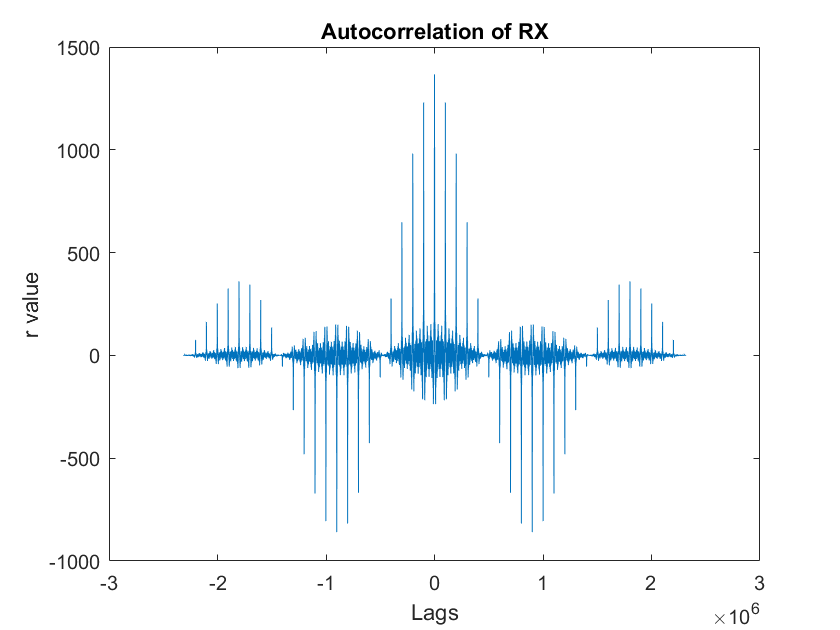

%Find autocorrelation of rx signal
[rauto, lagsauto] = xcorr(real(read), real(read));

%Plot autocorrelation
%plot_FT(rauto, 500000);
plot(lagsauto,rauto)
xlabel('Lags')
ylabel('r value')
title('Autocorrelation of RX')

## Cross-correlation of RX and TX (real part)

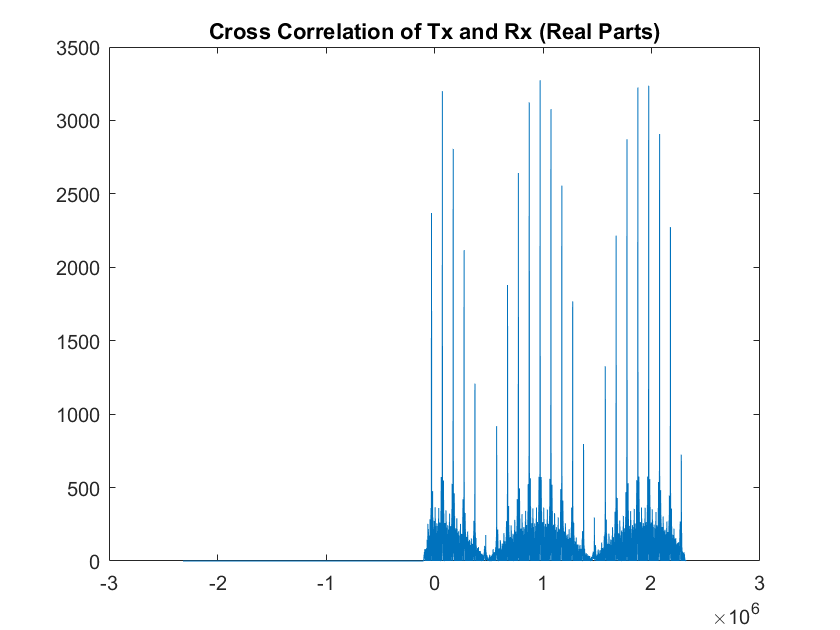

%Find cross-correlation of real part of received and transmitted signals
[r, lags]=xcorr(real(read),real(dat));

% Plot Cross-correlation
plot(lags,abs(r))
title('Cross Correlation of Tx and Rx (Real Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% Find the lag where the cross-correlation of rx/tx is greatest
% This indicates where the signal begins
startPos = lags(find(abs(r) == max(abs(r))))

startPos = 973349

## Cross-correlation of RX and TX (imaginary part)

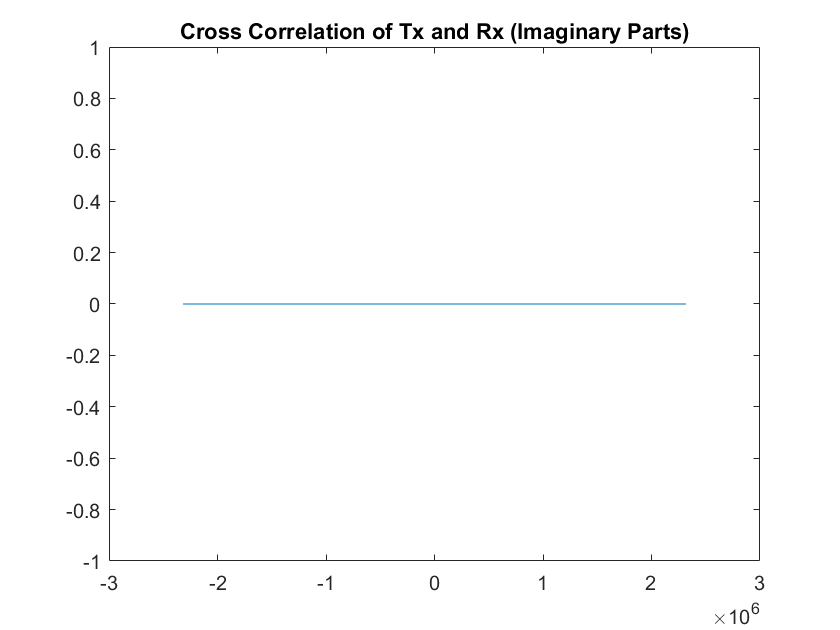

%Find cross-correlation of imaginary part of received and transmitted signals
[r, lags]=xcorr(imag(read),imag(dat));

% Plot Cross-correlation
plot(lags,r)
title('Cross Correlation of Tx and Rx (Imaginary Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% We transmitted a signal with no imaginary component

## Error Rate Calculation

% Downsample TX signal to get original signal
data_ds = downsample(dat,pulse_width);

% Isolate the portion of the received signal corresponding to the data we
% sent
read_shifted=read(startPos:end);
signal_rx = read_shifted(1:length(dat));

% If our signal always begins with -1s, we can fix the sign of our received
% data by multiplying by the negative of the sign of the first bit of the
% received data
signal_rx_sign = -sign(signal_rx(1))*signal_rx;

% Downsample the received signal, with a phase offset of half the pulse
% width
signal_rx = downsample(signal_rx_sign, pulse_width, pulse_width/2);

% Optionally add noise to perturb our signal during testing
% signal_rx_noise = signal_rx + sign(randn(length(signal_rx),1))*0.001;

% Calculate error rate
error=sign(real(signal_rx))-sign(real(data_ds));
err_num=length(find(error~=0));
err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 9.9900e-04

## Plot the RX vs. TX data

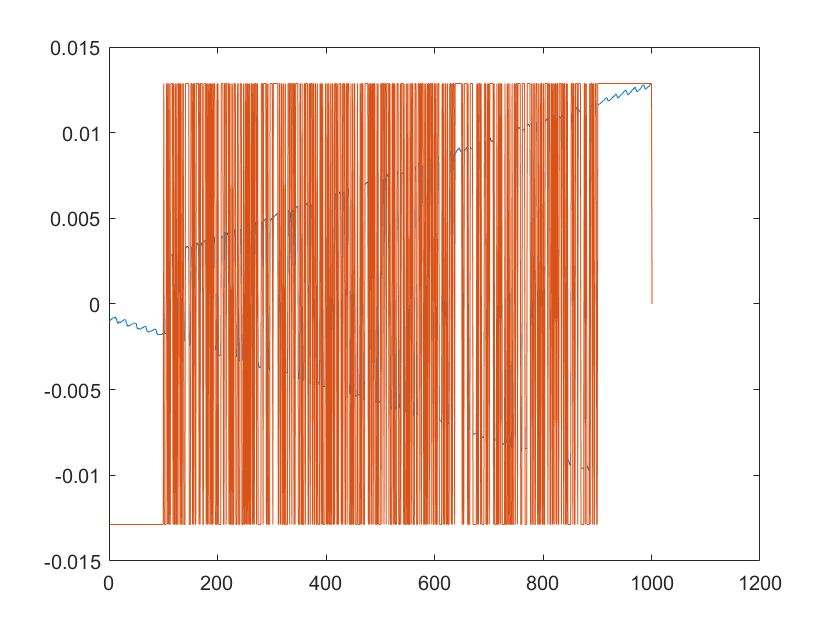

figure
ylim([-0.015,0.015])
%xlim([0,2e5])

% plot RX signal
plot(real(signal_rx))

% plot TX signal
hold on;

% scale the tx data by the max magnitude of the rx signal
plot_scale_factor = max(real(signal_rx));
tx_scaled_plot = real(data_ds)*plot_scale_factor;
plot(tx_scaled_plot)
hold off;

## Plot phase shift

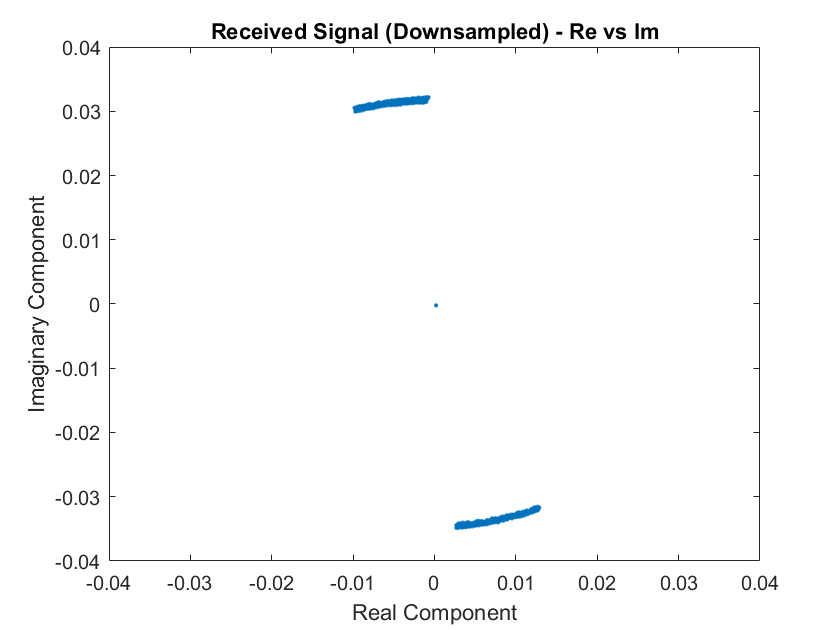

% plot real vs. imaginary component of downsampled rx signal
figure;
plot(real(signal_rx),imag(signal_rx),'.');
xlim([-0.04,0.04]);
title('Received Signal (Downsampled) - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

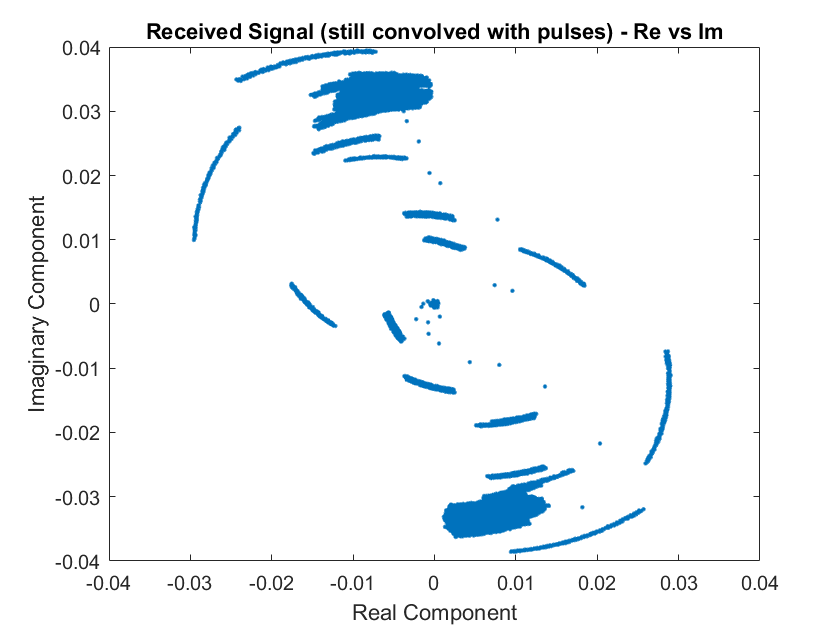


% plot real vs. imaginary component of upsampled (still convolved with pulses) rx signal
figure;
plot(real(signal_rx_sign),imag(signal_rx_sign),'.');
xlim([-0.04,0.04]);
title('Received Signal (still convolved with pulses) - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')